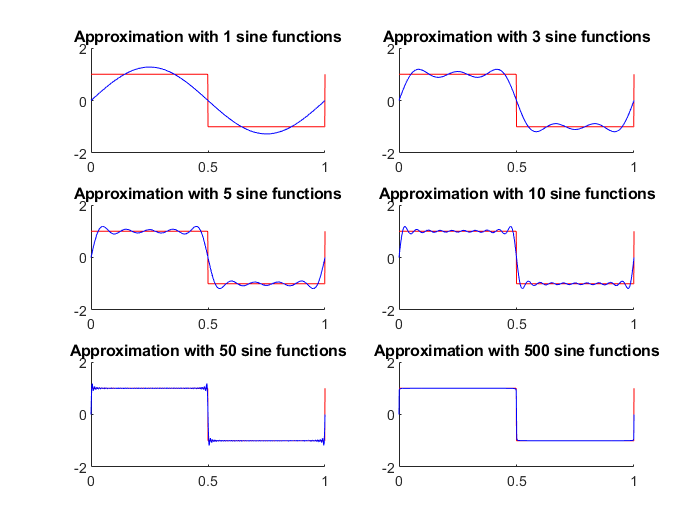

number = 1;
t = 0:0.001:1;
for n=[1,3,5,10,50,500]
    y = zeros(1,1001);
    for k = 1:2:2*n-1
        y = y + (4 / pi) * sin(2 * pi * k * t) / k;
    end
    subplot(3,2,number);
    hold on;
    sq = square(2 * pi * t);
    plot(t,sq,'r');
    plot(t,y,'b');
    hold off;
    number = number + 1;
    title(['Approximation with ', num2str(n),' sine functions']);
    axis ([0 1 -2 2]);
end